clear;clc;close all;fclose('all');
IFFT_FFT_LOOPBACK = false;
ENABLE_DELAY_CH = false;

# **OFDM PARAMETERS:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read OFDM Parameters from Info file from SW program
file = fopen('../Testing/OfdmInfo1.txt','r');
nfft = fscanf(file,"%d,",1);
BW = fscanf(file,"%d,",1); BW = BW*1000;
cp_len = fscanf(file, "%d,", 1);
M = fscanf(file,"%d,", 1);
ZP_density = fscanf(file,"%d,", 1);
symbol_guard_ms = fscanf(file,"%d,",1);
frame_guard_ms = fscanf(file,"%d,",1);
ofdm_symbols = fscanf(file,"%d,",1);
Fc = fscanf(file,"%d,",1); Fc = Fc * 1000;
tx_scale = fscanf(file,"%d",1);
fclose('all');
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fixed values
ZC_root = 13;
pilot_density = 0.25;
DAC_FS = 10000000;
nfft_p = 4*nfft; % For plotting spectrum
Delay_samples = nfft/2; % Baseband samples of Delay channel to exercise the synchronizer

# **CALCULATED OFDM PARAMETERS:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Parameters calculated from above configurable parameters
rep = 1/pilot_density;
first_pilot_carrier = ceil(nfft*50/100/2);
last_pilot_carrier = nfft-first_pilot_carrier;
zp_index1 = [1:first_pilot_carrier-1,last_pilot_carrier+1:nfft];
pilot_index = first_pilot_carrier:rep:last_pilot_carrier;
data_index = 1:nfft;
data_index([pilot_index,zp_index1]) = [];
scs = BW/nfft;
num_data_bits = length(data_index)*ofdm_symbols;
pilot_carriers = length(pilot_index);
data_carriers = length(data_index);
ind = find(data_index==nfft/2);
if (ind) % Set data DC subcarrier as ZP subcarrier
    data_index(ind) = [];
    data_carriers = data_carriers-1;
else
    %error('DC subcarrier is a pilot')
    warning('DC subcarrier is a pilot')
    ind = find(pilot_index==nfft/2);
    pilot_index(ind) = [];
    pilot_carriers = pilot_carriers-1;
end

zp_index = [1:first_pilot_carrier-1 nfft/2 last_pilot_carrier+1:nfft];
zp_carriers = length(zp_index);
n_packed = nfft*M;
Fs = BW; % Sample frequency (complex) = bandwidth
Interp_val = DAC_FS/Fs; % Interpolation value
if (ENABLE_DELAY_CH)
    Delay_interp = Delay_samples*Interp_val;
else
    Delay_interp = 0;
end
Ts = 1/Fs; % Sampling period
t = 0:Ts:(nfft+cp_len-1)*Ts; % Time vector for 1 OFDM symbol
t_up = 0:1/DAC_FS:((nfft+cp_len)*(ofdm_symbols+1)*Interp_val-1)*1/DAC_FS;
t_up_length = length(t_up);
t_up_rx = 0:1/DAC_FS:(t_up_length+Delay_interp*2)*1/DAC_FS-1/DAC_FS; % time vector adding delay
F = (-nfft_p/2:nfft_p/2-1)/nfft_p*Fs; % Plotting baseband spectrum
F_up = (-nfft_p/2:nfft_p/2-1)/nfft_p*DAC_FS; % Plotting DUC spectrum

# **QAM MODULATION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read message symbols:
file = fopen('../Testing/TxModData1.txt','r');
tmp = fscanf(file,"%d",3); % Throw away header
data_char = fscanf(file,"%d",(data_carriers)*ofdm_symbols);
fclose('all');
data = reshape(data_char, [data_carriers ofdm_symbols]);
mod_data = data;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% QAM Modulation (frequency domain)
qam_mod_data = qammod(data,M);

# **CARRIER ALLOCATION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Generate random pilot data
rng default
pilot_data = randsrc(pilot_carriers,ofdm_symbols,0:M-1);
reference_pilot = qammod(pilot_data,M);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% set ZP carriers equal to zero
zp_carrier = complex(0,0);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Finish carrier allocation
carriers = zeros(nfft,ofdm_symbols);
carriers(pilot_index,:) = reference_pilot;
carriers(data_index,:) = qam_mod_data;
carriers(zp_index,:) = zp_carrier;
carriers = carriers*tx_scale;

# **SYNCHRONIZATION SYMBOL:**

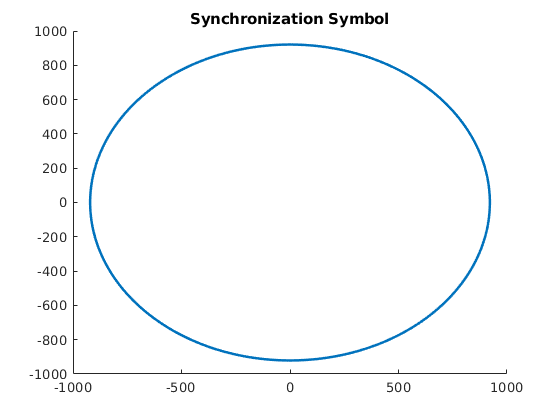

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create Zadoff-Chu sequence
sync_tx = tx_scale*exp(-1i*pi*ZC_root*(1:nfft).*((1:nfft)+1)/nfft);
sync_tx_cp = [sync_tx zeros(1,cp_len)]; % Insert Guard period after sync symbol instead of CP
% Insert ZC sequence infront of first OFDM symbol
carriers = horzcat(sync_tx.',carriers);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),scatter(real(sync_tx),imag(sync_tx),'.'),title('Synchronization Symbol')

# **IFFT:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Ifftshift to reorder carriers in correct order for IFFT
ifft_signal = zeros(nfft,ofdm_symbols+1);
% Do ifftshift in a loop so that it works per symbol - easer in SW
for i=1:ofdm_symbols+1
    ifft_signal(:,i) = ifft(ifftshift(carriers(:,i)),nfft);
end
sync_tx_time = ifft_signal(:,1);

# **CP INSERTION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Cyclic Prefix (copy end of symbol to beginning
cp_start = nfft-cp_len;
cp = ifft_signal(cp_start+1:end,:);
cp(:,1) = complex(0,0); % No CP for synchronization symbol
ofdm_tx_signal_par = vertcat(cp,ifft_signal);

# **PARALLEL TO SERIAL:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
ofdm_tx_signal_ser = reshape(ofdm_tx_signal_par,[1 (nfft+cp_len)*(ofdm_symbols+1)]);
%ofdm_tx_signal_ser(1:nfft) = sync_tx;

# **DUC:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Nearly ideal MATLAB DUC:
[ofdm_duc_signal, duc_coef] = interp(ofdm_tx_signal_ser,Interp_val,10,1);

# **IQ MIXER:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Use oscillator at Fc
phi = rand(1);
ofdm_duc_signal_i = real(ofdm_duc_signal).*cos(2*pi*Fc*t_up+phi);
ofdm_duc_signal_q = imag(ofdm_duc_signal).*-sin(2*pi*Fc*t_up+phi);
ofdm_duc_signal_real = ofdm_duc_signal_i + ofdm_duc_signal_q;

# **SIGNAL ANALYSIS:**

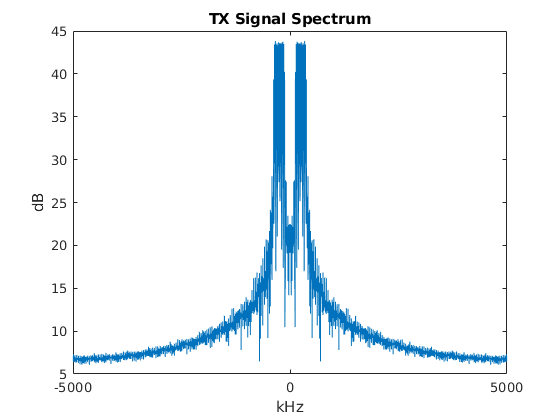

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(),plot(F_up/1000,10*log10(abs(fftshift(fft(ofdm_duc_signal_real,nfft_p)))))
title('TX Signal Spectrum'),xlabel('kHz'),ylabel('dB')

# **CHANNEL:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% White noise
SNR = 30;
ofdm_signal_ch = awgn(ofdm_duc_signal_real,SNR);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Multipath
multipath = [0 0.1 0.05 0 0.9 0 0 0.9 0.3 0.5 0.6 0.8 0 0 0.7];
ofdm_signal_ch = filter(multipath,1,ofdm_signal_ch);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Delay
ofdm_signal_ch = [ofdm_signal_ch(end-Delay_interp+1:end),ofdm_signal_ch ofdm_signal_ch(end-2*Delay_interp+1:end-Delay_interp)];

# **IQ MIXER:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
phi = rand(1);
i_ddc = ofdm_signal_ch .* cos(2*pi*Fc*t_up_rx+phi);
q_ddc = ofdm_signal_ch .* -sin(2*pi*Fc*t_up_rx+phi);
ddc_signal = complex(i_ddc,q_ddc);

# **DDC:**

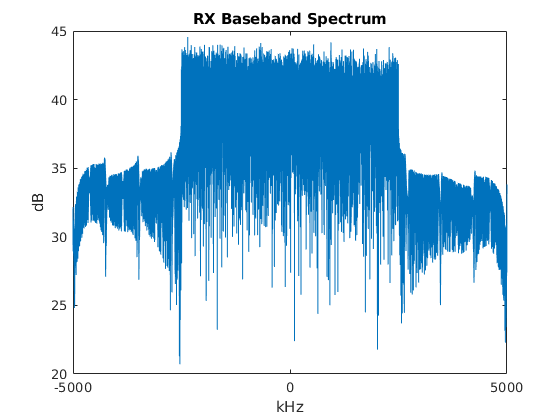

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Matlab near ideal function
ddc_base_signal = decimate(ddc_signal,Interp_val,4096,'Fir');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(),plot(F_up/1000,10*log10(abs(fftshift(fft(ddc_base_signal,nfft_p)))))
title('RX Baseband Spectrum'),xlabel('kHz'),ylabel('dB')

# **SYNCHRONIZATION:**

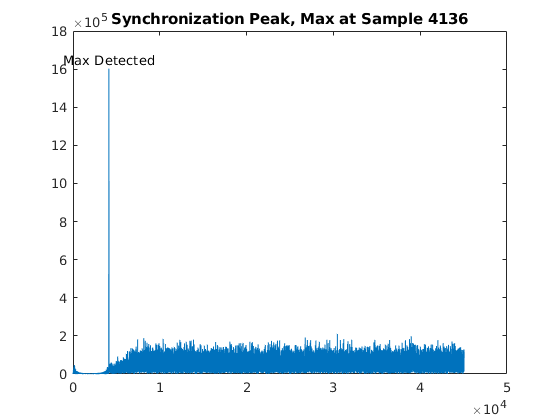

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Synchronization is detected in frequency domain
sync_rx_carriers = [];
loop_sig_length = floor(length(ddc_base_signal)/nfft);
loop_rem = mod(length(ddc_base_signal),nfft);
for i = 1:loop_sig_length % Take FFT
    sync_rx_carriers = [sync_rx_carriers fftshift(fft(ddc_base_signal((i-1)*nfft+1:i*nfft),nfft))];
    if (i == loop_sig_length)
       sync_rx_carriers = [sync_rx_carriers fftshift(fft([ddc_base_signal(i*nfft+1:end),zeros(1,nfft-loop_rem)],nfft))];
    end
end
sync_rx_carriers = ddc_base_signal;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Perform synchronization with filter insead of xcorr
% Define the matched filter as the time-reversed complex conjugate 
% of the ZC sequence.
sync_coef = conj(fliplr(sync_tx_time)); % Matched filter
sync_corr_filt = abs(filter(sync_coef,1,sync_rx_carriers)); 
[val,ind] = max(sync_corr_filt);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Delete the Synchronization symbol and everything before it as well as
% everything after the last symbol
ofdm_rx_sync_signal = ddc_base_signal;
ofdm_rx_sync_signal([1:ind,ind+1+(nfft+cp_len)*ofdm_symbols:end]) = []; % Delete


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),plot(sync_corr_filt),hold on,text(ind,val,'Max Detected','HorizontalAlignment','center','VerticalAlignment','bottom')
title(['Synchronization Peak, Max at Sample ',num2str(ind)])

# **SERIAL TO PARALLEL:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if (IFFT_FFT_LOOPBACK)
    ofdm_rx_sync_signal = ofdm_tx_signal_ser;
end
ofdm_rx_signal = reshape(ofdm_rx_sync_signal,[nfft+cp_len ofdm_symbols]);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.

# **CP REMOVAL + CFO CORRECTION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Save and remove CP
cp_rm_signal = ofdm_rx_signal;
cp_rm_signal(1:cp_len,:) = [];

# **FFT:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% fftshift per symbol:
fft_signal = zeros(nfft,ofdm_symbols);
for i = 1:ofdm_symbols
    fft_signal(:,i) = fftshift(fft(cp_rm_signal(:,i),nfft));
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),scatter(real(fft_signal),imag(fft_signal),'.'),title('No Equalization')

# **EQUALIZATION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get RX pilots
fft_signal_eq = fft_signal;
P_RX = fft_signal_eq(pilot_index,:); % Get RX Pilots
H = conj(P_RX)./conj(reference_pilot);
H_interp = interp1(pilot_index,H,1:nfft,'previous');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Check if pilots wrap data
if (last_pilot_carrier ~= pilot_index(end))
    if (last_pilot_carrier-1 ~= pilot_index(end))
        if (last_pilot_carrier-2 ~= pilot_index(end))
            disp('Pilots do no wrap, setting last pilot to previous pilot')
            H_interp(data_index(end-2),:) = H_interp(data_index(end-3),:);
        end
        disp('Pilots do no wrap, setting last pilot to previous pilot')
        H_interp(data_index(end-1),:) = H_interp(data_index(end-2),:);
    end    
    disp('Pilots do no wrap, setting last pilot to previous pilot')
    H_interp(data_index(end),:) = H_interp(data_index(end-1),:);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Equalize data with channel estimates
Z_EQ_ZF = (fft_signal_eq)./conj(H_interp);

# **CARRIER DEALLOCATION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Z_EQ_Data = Z_EQ_ZF;
Z_EQ_Data([pilot_index,zp_index],:) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Read Equalizer Output from SW
file = fopen('../Testing/RxFreqDataEQ1.txt','r');
% Throw away header
tmp = fscanf(file,"%d,",1);
tmp = fscanf(file,"%d,",1);tmp = fscanf(file,"%d,",1);
Z_EQ_sw_split = fscanf(file,"%d, %d", [2 nfft*ofdm_symbols]);
Z_EQ_sw = complex(Z_EQ_sw_split(1,:),Z_EQ_sw_split(2,:));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot
figure(),scatter(real(Z_EQ_Data),imag(Z_EQ_Data),'.'),title('MATLAB')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot animation of constellation
figure()
for i=1:ofdm_symbols
    scatter(real(Z_EQ_Data(:,i)),imag(Z_EQ_Data(:,i)),'.')
    pause(0.01)
end
title('MATLAB - Equalized')

# **QAM DEMODULATION:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Demod
demod_data = qamdemod(Z_EQ_Data,M);
demod_data_ser = qamdemod(Z_EQ_Data,M);

# **ANALYSIS:**

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Error Rate
ser_mat = symerr(data, demod_data)/numel(data);
ser_sw = symerr(data, demod_data_ser)/numel(data);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Get EVM Measurements
evm = comm.EVM(AveragingDimensions=[1 2],MaximumEVMOutputPort=1);
[mat_evm,mat_evm_pk] = evm(qam_mod_data,Z_EQ_Data);
[sw_evm,sw_evm_pk] = evm(qam_mod_data,Z_EQ_Data);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot table
Equalization = ["MATLAB";"SW"];
SER = [ser_mat;ser_sw];
AverageEVM = [mat_evm;sw_evm];
PeakEVM = [mat_evm_pk;sw_evm_pk];
figure(),table(Equalization,SER,AverageEVM,PeakEVM)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot EVM
evm = comm.EVM(AveragingDimensions=2);
